load pnts.mat

A=pntsTest1;
B=pntsTest2;

[c1,r1] = size(A);
[c2,r2] = size(B);
%Number of points
Na = r1;    
    
%Compute the centroid of each point set
Ca = mean(A,2);
Cb = mean(B,2);

%Remove the centroid
An = A - repmat(Ca,1,Na);
Bn = B - repmat(Cb,1,Na);

%Compute the quaternions
M = zeros(4,4);
invTest=zeros(4,4);
for i=1:Na 
    %Shortcuts
    a = [0;An(:,i)];
    b = [0;Bn(:,i)];    
    %Crossproducts
    Ma = [  a(1) -a(2) -a(3) -a(4) ; 
            a(2)  a(1)  a(4) -a(3) ; 
            a(3) -a(4)  a(1)  a(2) ; 
            a(4)  a(3) -a(2)  a(1)  ];
    Mb = [  b(1) -b(2) -b(3) -b(4) ; 
            b(2)  b(1) -b(4)  b(3) ; 
            b(3)  b(4)  b(1) -b(2) ; 
            b(4) -b(3)  b(2)  b(1)  ];
    %Add up
    M = M + Ma'*Mb;
    invTest=Ma';
end


%Compute eigenvalues
[E D] = eig(M);

%Compute the rotation matrix
e = E(:,4);
M1 = [  e(1) -e(2) -e(3) -e(4) ; 
        e(2)  e(1)  e(4) -e(3) ; 
        e(3) -e(4)  e(1)  e(2) ; 
        e(4)  e(3) -e(2)  e(1)  ];
M2 = [  e(1) -e(2) -e(3) -e(4) ; 
        e(2)  e(1) -e(4)  e(3) ; 
        e(3)  e(4)  e(1) -e(2) ; 
        e(4) -e(3)  e(2)  e(1)  ];


R = M1'*M2;



myStr=mat2str(pntsTest1)

myStr = '[-0.078525997698307 -0.112035997211933 -0.470306992530823 0.421945989131927 -0.0415760017931461;0.0820880010724068 -0.244963005185127 -0.249103993177414 -0.206649005413055 -0.506470024585724;1.71200001239777 1.56099998950958 1.51900005340576 1.6360000371933 1.68499994277954]'

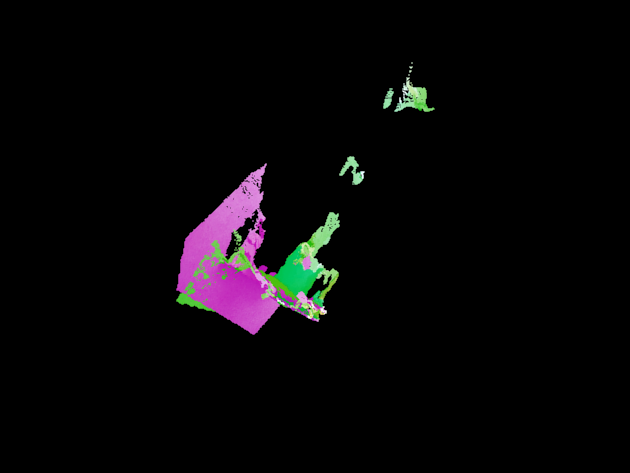

[R, T, err] = absoluteOrientationQuaternion(pntsTest1,pntsTest2);
tform = rigidtform3d(R,T);
pcNew=pctransform(pc1,tform);
pcshowpair(pcNew,pc2);

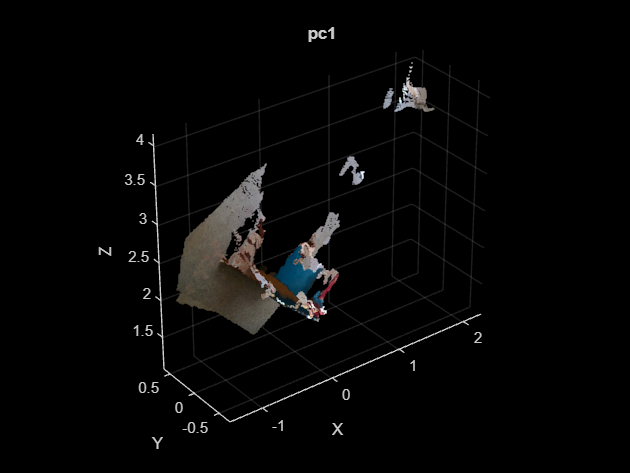

pcCombined=pcmerge(pcNew,pc2,0.001);

pcshow(pcCombined, "AxesVisibility","on")
xlabel('X');
ylabel('Y');
zlabel('Z');
title("pc1")

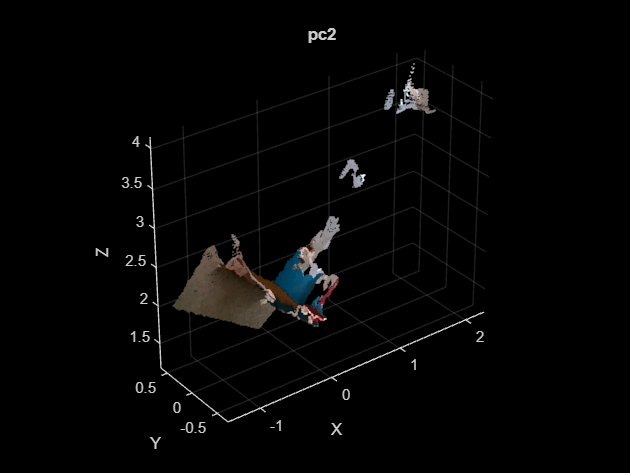

fig2=figure;
pcshow(pc2, "AxesVisibility","on")
xlabel('X');
ylabel('Y');
zlabel('Z');
title("pc2")